## Problem Set 1

**October 1, 2026**

### **I. Deterministic Dynamic Programming**

#### **1. a) Dynamic optimization problem**

$v(K_0) = \max_{\{c_t | c_t \in C(K_t)\}_{t=0}^{\infty}} \sum_{t=0}^{\infty} \beta ^t \ln{c_t}$  where $C(K_t)$ is the set of feasible consumption levels given $K_t$ ,

s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t$

         $c_t, K_t \geq 0$  $\forall t = 0, 1, 2, ...$ , and

          $K_0$ given,

where $\beta = \frac{1}{1+\rho}$  henceforth.

#### b) Bellman equation


$$v(K_t) = \max_{c_t \in C(K_t)} \ln{c_t} + \beta v(K_{t+1})$$


s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t$

         $c_t, K_{t+1} \geq 0$ .

#### c) Interpretation

The value function is $v(K_t)$ which represents the present discounted value from now on of the stream of per-period payoffs when consumption is chosen optimally, given the current state of farm capital $K_t$.

The continuation value is $v(K_{t+1})$ which represents the value of all future payoffs starting from the next period when consumption is chosen optimally given next period's capital stock, which involves a tradeoff with today's choice of consumption.

#### d) Redefine control variable


$$v(K_t) = \max_{K_{t+1}} \ln {(aK_t - \frac{bK_t^2}{2} - K_{t+1} + K_t})+ \beta v(K_{t+1})$$


s.t. $0 \leq K_{t+1} < aK_t - \frac{bK_t^2}{2} + K_t$ .

#### e) Solve for value, policy function

In the following code block, I solve for the value function and policy function as functions of capital stock K. In lines 7-10, I set parameter values as given in the problem. In lines 13-17, I set up the discretized K arrays. In lines 20-22,I define `f_k` as production plus existing capital, which is the total resources available. Subtracting K′ gives consumption, and taking the log gives the payoff matrix. I then initialize values for the loop in lines 25-27. The while loop in lines 30 to 42 calculates for each K, K' pair the value function, finds the arg max, and continues looping until the value function converges as defined by our "diff" condition. The arg max (K' that maximizes value for each K) is identified as "kprime_pol", the policy function. 

% Setup
clearvars;
close all;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 3;

% Create k grids
num_k = 30;
num_kprime = 30;

k = (1:num_k)';
kprime = 1:num_kprime;

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - kprime; % consumption for every pair
pii = log(c); % payoffs

% Initialize for loop
v = zeros(num_k, 1);
ep = 1e-6;
diff = 1;

% Solve
while diff > ep
    % Reset v to be the previous version
    v_old = v;

    % value of v
    vv = pii + beta * v';

    % For each k, choose kprime to maximize vv
    [v, kprime_pol] = max(vv, [], 2);

    % Calculate diff
    diff = max(abs(v - v_old));
end

% Print results in table
results = table(k, v, kprime_pol, 'VariableNames', {'State', 'Value', 'Policy'})

results = 30×3 table
    State    Value     Policy
    _____    ______    ______

      1      122.55      13  
      2      123.39      15  
      3      123.82      15  
      4      124.11      15  
      5      124.31      16  
      6      124.47      16  
      7      124.59      16  
      8      124.69      16  
      9      124.77      16  
     10      124.84      16  
     11      124.89      16  
     12      124.93      16  
     13      124.96      16  
     14      124.99      16  
     15         125      16  
     16      125.01      16  

	Get insights using Copilot


#### f) Plot optimal trajectories

Here I solve for the optimal trajectories of capital K(t) and consumption C(t) starting from K₀ = 5. In lines 47-51, I set the number of periods T and initialize the capital path with K₀ = 5. In lines 54-56, I use the policy function to fill in the rest of the capital path: for each period, next period's capital is the policy function evaluated at the current capital. In line 59, I compute consumption in each period from the law of motion, as production plus current capital minus next period's capital. In lines 65-72, I plot both paths against time."

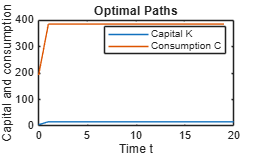

% Pick number of periods
T = 20;

% Store capital in vector
k_path = zeros(T + 1, 1);
k_path(1) = 5; % start at period 5

% Simulate the optimal capital path
for t = 1:T
    k_path(t + 1) = kprime_pol(k_path(t));
end

% Consumption from law of motion
c_path = f_k(k_path([1:T])) - k_path([2:T + 1]);

% Plot optimal paths
t_k = 0:T;
t_c = 0:T-1;

figure
plot(t_k, k_path)
hold on
plot(t_c, c_path)
legend('Capital K', 'Consumption C')
xlabel('Time t')
title('Optimal Paths')
ylabel('Capital and consumption')

#### g) Interpret results

The value function v(K) rises with capital up to K = 16 and then falls slightly. The policy function shows that for most starting values of K, the optimal next-period capital is K′ = 16, so 16 is the steady state. Starting from K₀ = 5, capital rises to 16 in only one period and stays there. This one-period jump is partially due to the coarse grid for K (integers 1-30 only). Consumption starts near 190 units and rises to about 385 which is the steady-state output, F(16). We can see that the farming family gives up some consumption early to build capital, which raises consumption in every later period.